# CCLE Ratios

**Author**: Scott Campit

## Summary

## Load data

### Entire dataset

% First we need to clean up the metabolomics dataset
metabolomics = readtable('CCLE_metabolomics_ratios.xlsx', 'sheet', 'all')

metabolomics = 927×52 table
      CCLE_ID       G3P_AKG    FUM_AKG    SUCC_AKG    GLY_AKG    SER_AKG    MET_AKG    THR_AKG    DMG_AKG    SAH_AKG    BET_AKG    CHO_AKG    CIT_NAD    VAL_NAD    LEU_NAD    ISO_NAD    ALA_NAD    AC_NAD     C46_2_TAG_NAD    C46_1_TAG_NAD    C46_0_TAG_NAD    C48_3_TAG_NAD    C48_2_TAG_NAD    C48_1_TAG_NAD    C48_0_TAG_NAD    C50_3_TAG_NAD    C50_2_TAG_NAD    C50_1_TAG_NAD    C50_0_TAG_NAD    C52_5_TAG_NAD    C52_4_TAG_NAD    C52_3_TA

metabolomics_ccl = metabolomics(:, 'CCLE_ID')

metabolomics_ccl = 927×1 table
      CCLE_ID   
    ____________

    {'DMS53'   }
    {'SW1116'  }
    {'NCIH1694'}
    {'P3HR1'   }
    {'HUT78'   }
    {'UMUC3'   }
    {'HOS'     }
    {'HUNS1'   }
    {'AML193'  }
    {'RVH421'  }
    {'NCIH1184'}
    {'TC71'    }
    {'NCIH2227'}
    {'SNU449'  }
    {'NCIH28'  }
    {'OV56'    }


% Next, we need to map between datasets
gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'all')

gcp = 866×43 table
      CellLine       H3K4me0       H3K4me1      H3K4me2       H3K4ac1     H3K9me0K14ac0    H3K9me1K14ac0    H3K9me2K14ac0    H3K9me3K14ac0    H3K9ac1K14ac0    H3K9me0K14ac1    H3K9me1K14ac1    H3K9me2K14ac1    H3K9me3K14ac1    H3K9ac1K14ac1    H3K18ac0K23ac0    H3K18ac1K23ac0    H3K18ac0K23ac1    H3K18ac1K23ac1    H3K18ac0K23ub1    H3K27me0K36me0    H3K27me0K36me1    H3K27me0K36me2    H3K27me0K36me3    H3K27me1K36me0    H3K27me1K36me1    H3K27me1K36me2    H3K27me1K36me3    H3K27me2K36me0

[~, ia, ib] = intersect(string(table2cell(metabolomics(:, 'CCLE_ID'))), ...
                        string(table2cell(gcp(:, 'CellLine'))));
                    
% Finally, let's get tables with matching indicies
metabolomics = metabolomics(ia, :);
gcp = gcp(ib, :);

### Methylation and acetylation subsets

% I will also load data subsets and map them
methylation_metabolomics = readtable('CCLE_metabolomics_ratios.xlsx', 'sheet', 'Methylation')

methylation_metabolomics = 927×12 table
      CCLE_ID       G3P_AKG    FUM_AKG    SUCC_AKG    GLY_AKG    SER_AKG    MET_AKG    THR_AKG    DMG_AKG    SAH_AKG    BET_AKG    CHO_AKG
    ____________    _______    _______    ________    _______    _______    _______    _______    _______    _______    _______    _______

    {'DMS53'   }     1.0067    0.98979     1.0281      1.1269     0.9231     1.1267     1.1587     1.0369      1.014     1.1396     1.1921
    {'SW1116'  }    0.87865    0.99222     1.0254      1.1531     1.1802     1.1423     1.2008    0.99674     0.9757     1.0239    0.9

methylation_gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'methylation')

methylation_gcp = 866×14 table
      CellLine       H3K4me1      H3K4me2      H3K9me1      H3K9me2      H3K9me3      H3K36me1     H3K36me2    H3K36me3     H3K27me1     H3K27me2     H3K27me3    H3K79me1     H3K79me2 
    ____________    _________    __________    ________    _________    __________    _________    ________    _________    _________    _________    ________    _________    _________

    {'DMS53'   }     -0.15314      -0.34861    -0.71971     -0.20808     -0.033416      0.28749     0.64687     -0.14569  

methylation_metabolomics = methylation_metabolomics(ia, :);
methylation_gcp = methylation_gcp(ib, :);

acetylation_metabolomics = readtable('CCLE_metabolomics_ratios.xlsx', 'sheet', 'Acetylation')

acetylation_metabolomics = 927×40 table
      CCLE_ID       CIT_NAD    VAL_NAD    LEU_NAD    ISO_NAD    ALA_NAD    AC_NAD     C46_2_TAG_NAD    C46_1_TAG_NAD    C46_0_TAG_NAD    C48_3_TAG_NAD    C48_2_TAG_NAD    C48_1_TAG_NAD    C48_0_TAG_NAD    C50_3_TAG_NAD    C50_2_TAG_NAD    C50_1_TAG_NAD    C50_0_TAG_NAD    C52_5_TAG_NAD    C52_4_TAG_NAD    C52_3_TAG_NAD    C52_2_TAG_NAD    C52_1_TAG_NAD    C54_7_TAG_NAD    C54_6_TAG_NAD    C54_5_TAG_NAD    C54_4_TAG_NAD    C54_3_TAG_NAD    C54_2_TAG_NAD    

acetylation_gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'acetylation')

acetylation_gcp = 866×7 table
      CellLine       H3K4ac1      H3K9ac1      H3K14ac1     H3K18ac1      H3K23ac1      H3K27ac1 
    ____________    _________    _________    __________    _________    ___________    _________

    {'DMS53'   }      -1.4171     -0.96782       -1.1501      0.24962      -0.088407      0.39618
    {'SW1116'  }     -0.17028     0.062518       -0.5177    -0.015737    -0.00063681      -1.1987
    {'NCIH1694'}      0.41395     -0.42716        0.2155      0.51212        0.30843     0.055683
    {'P3HR1'   }     0.079932      0.20833       0.18223     -0.24954        0.53282       1.0983
    {'HUT78'   }      0.35742    -0.059567       0.84508     -0.33189        0.43724     -0.18524
    {'HOS'     }      -0.1007     -0.58862   

acetylation_metabolomics = acetylation_metabolomics(ia, :);
acetylation_gcp = acetylation_gcp(ib, :);

## Get correlations between metabolomics ratios and GCP

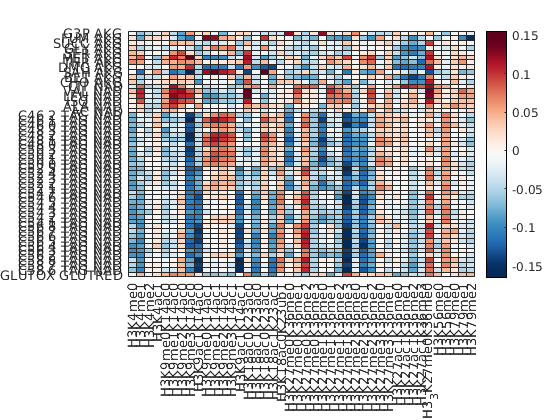

% Get data subsets
X = table2array(gcp(:, 2:end)); X(isnan(X)) = 0;
Y = table2array(metabolomics(:, 2:end)); Y(isnan(Y)) = 0;
metabolites = metabolomics.Properties.VariableNames(2:end);
markers = gcp.Properties.VariableNames(2:end);

% Compute pearson correlation coefficient matrix
[pearsonmat, pearsonpval] = corr(X, Y, ...
                                 'Type', 'Pearson');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(pearsonmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

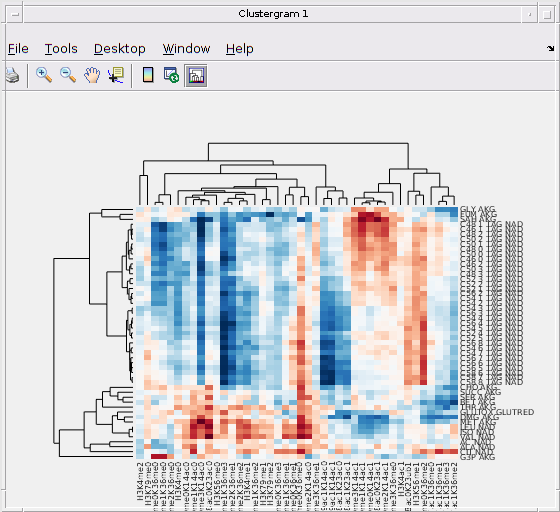

Clustergram object with 51 rows of nodes and 42 columns of nodes.



% Plot clustergram without p-value mask
clustergram(pearsonmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

### Applying a mask

Next, I decided to look at these matrices using the p-value mask. Because there are NaNs, we can't make a clustergram for this set. 

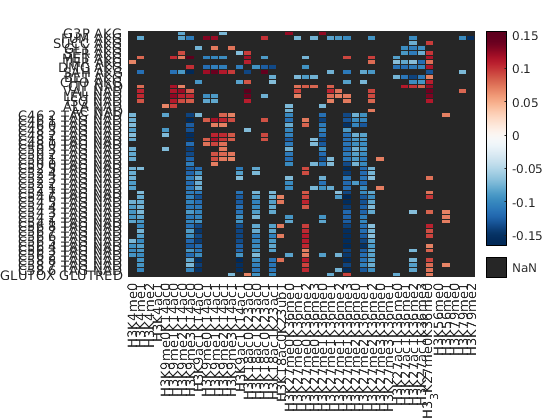

mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

### Metabolic subsets

#### All data

Of course, because we're showing all the histone markers and all metabolites, this is pretty terrible to analyze. Let's start simplifying by removing histone markers I'm not interested in analyzing.

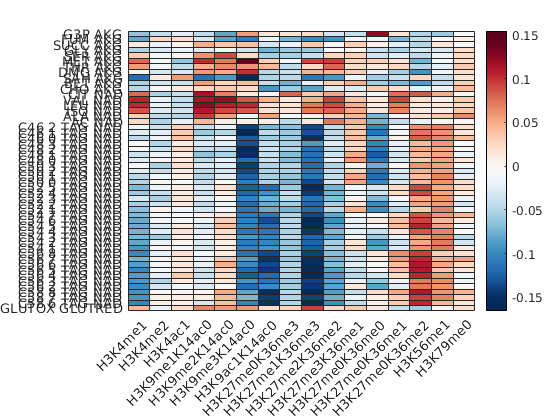

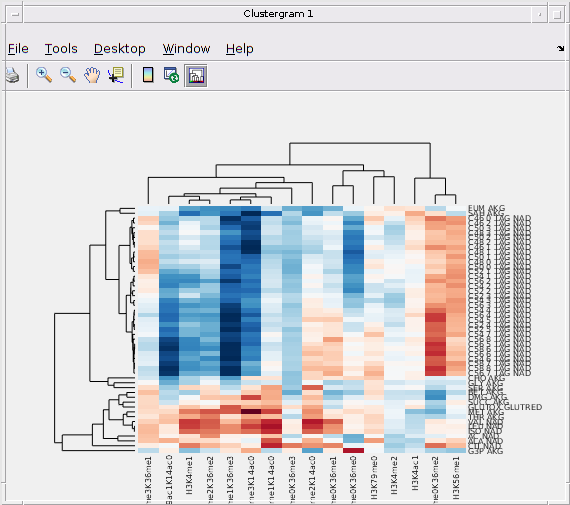

Clustergram object with 51 rows of nodes and 16 columns of nodes.



metabolic_subset = [2, 3, 4, ...        % H3K4
                    6, 7, 8, 9, ...     % H3K9
                    23, 27, 30, 32, ... % H3K27
                    20, 21, 22, ...     % H3K36
                    39, 40];            % H3K79
pearsonmat_metab = pearsonmat(metabolic_subset, :);
pearsonpval_metab = pearsonpval(metabolic_subset, :);
metab_markers = markers(metabolic_subset);
heatmap(pearsonmat_metab', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', metab_markers)
clustergram(pearsonmat_metab', ...
            'RowLabels', metabolites, ...
            'ColumnLabels', metab_markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

#### Mask

Add a p-value mask to this metabolic subset.

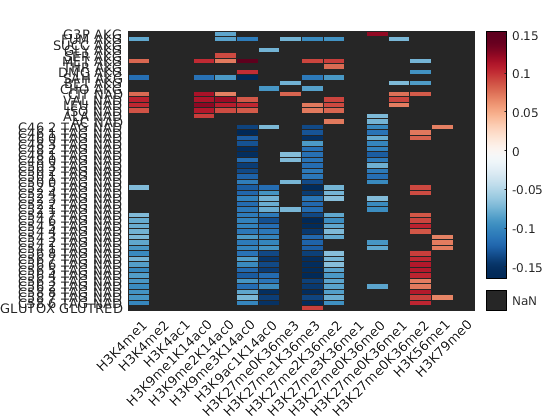

mask = pearsonmat_metab;
mask(pearsonpval_metab > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', metab_markers)

### Pearson correlation coefficient of the Methylation subset

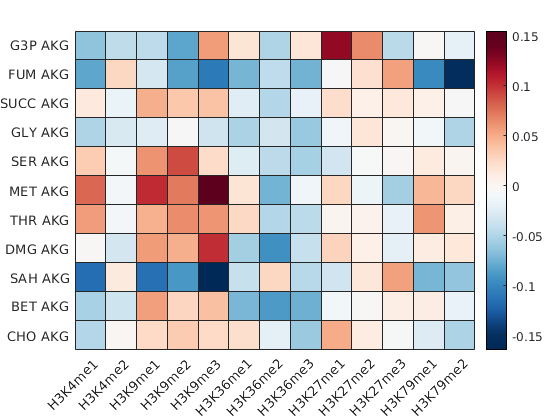

% Get data subsets
X = table2array(methylation_gcp(:, 2:end)); X(isnan(X)) = 0;
Y = table2array(methylation_metabolomics(:, 2:end)); Y(isnan(Y)) = 0;
metabolites = methylation_metabolomics.Properties.VariableNames(2:end);
markers = methylation_gcp.Properties.VariableNames(2:end);

% Compute pearson correlation coefficient matrix
[pearsonmat, pearsonpval] = corr(X, Y, ...
                                 'Type', 'Pearson');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(pearsonmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

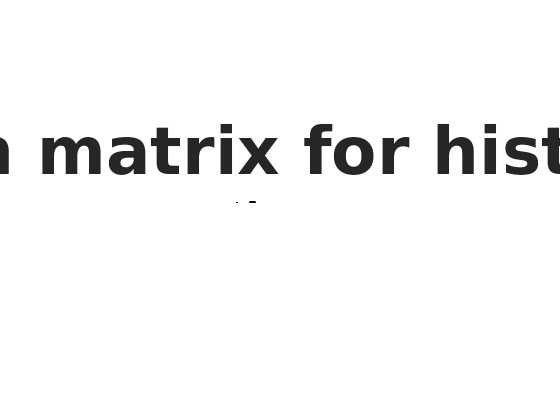

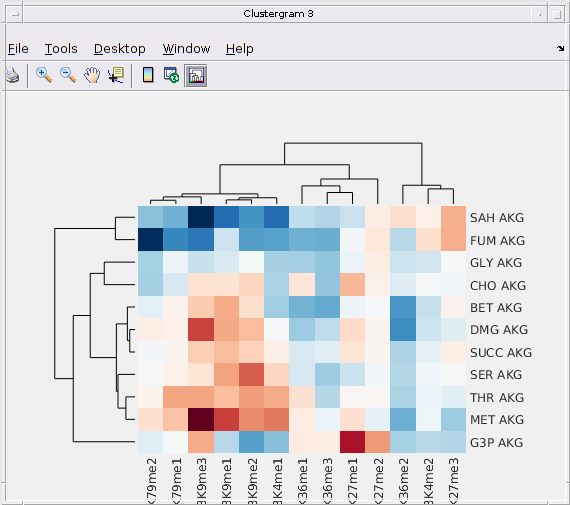

Clustergram object with 11 rows of nodes and 13 columns of nodes.



    
mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers, ...
        'Title', 'Filtered correlation matrix for histone methylation', ...
        'FontSize', 45, ...
        'XLabel', 'Methylation Markers', ...
        'YLabel', 'Metabolites Ratios')
% Plot clustergram without p-value mask
clustergram(pearsonmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)

figureHandle = gcf;
%# make all text in the figure to size 14 and bold
set(findall(figureHandle,'type','text'), ...
            'fontSize',30,...
            'fontWeight','bold')

### Applying a mask

Next, I decided to look at these matrices using the p-value mask. Because there are NaNs, we can't make a clustergram for this set. 

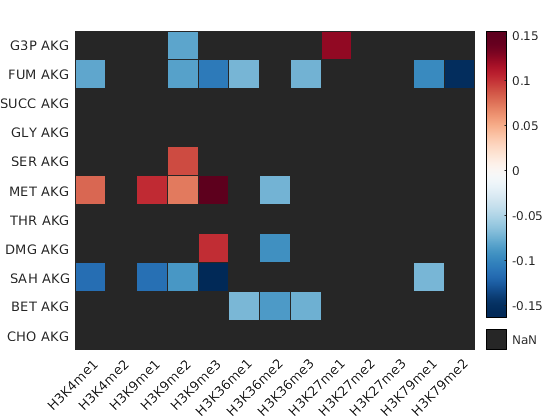

mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)

### Pearson correlation coefficient of the Acetylation subset

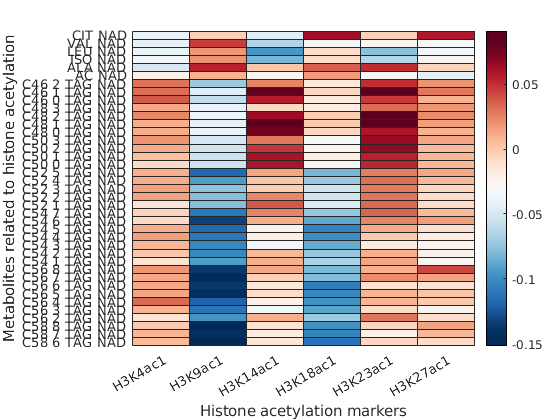

% Get data subsets
X = table2array(acetylation_gcp(:, 2:end)); X(isnan(X)) = 0;
Y = table2array(acetylation_metabolomics(:, 2:end)); Y(isnan(Y)) = 0;
metabolites = acetylation_metabolomics.Properties.VariableNames(2:end);
markers = acetylation_gcp.Properties.VariableNames(2:end);

% Compute pearson correlation coefficient matrix
[pearsonmat, pearsonpval] = corr(X, Y, ...
                                 'Type', 'Pearson');

% Plot correlation matrix without p-value mask                            
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
metabolites = strrep(metabolites, '_', ' ');
heatmap(pearsonmat', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers)
xlabel('Histone acetylation markers');
ylabel('Metabolites related to histone acetylation')

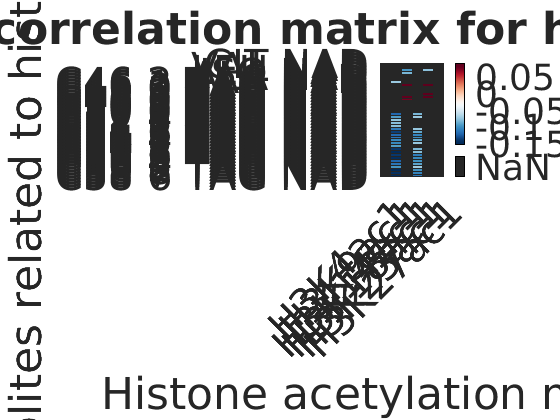

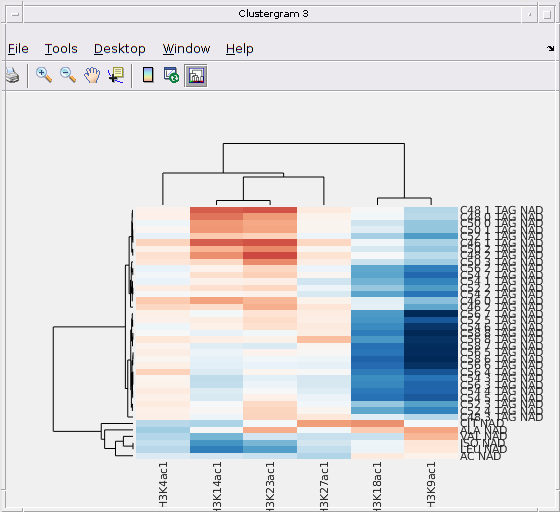

Clustergram object with 39 rows of nodes and 6 columns of nodes.




mask = pearsonmat;
mask(pearsonpval > 0.05) = NaN;

% Plot correlation matrix without p-value mask                            
heatmap(mask', 'colormap', redbluecmap, ...
        'YData', metabolites, ...
        'XData', markers, ...
        'Title', 'Filtered correlation matrix for histone methylation', ...
        'Fontsize', 30)
xlabel('Histone acetylation markers');
ylabel('Metabolites related to histone acetylation')

% Plot clustergram without p-value mask
clustergram(pearsonmat', ...
            'RowLabels', metabolites', ...
            'ColumnLabels', markers, ...
            'RowPdist', 'correlation', ...
            'ColumnPdist', 'correlation', ...
            'Colormap', redbluecmap)